path = 'D:\OneDrive - University of Moratuwa\Volume D\FYP\Simulation\Banana\in-silico-model\pwdb_data.mat'; 
% path = 'D:\OneDrive - University of Moratuwa\Volume D\FYP\Simulation\Banana\pwdb_data.mat';
load(path);

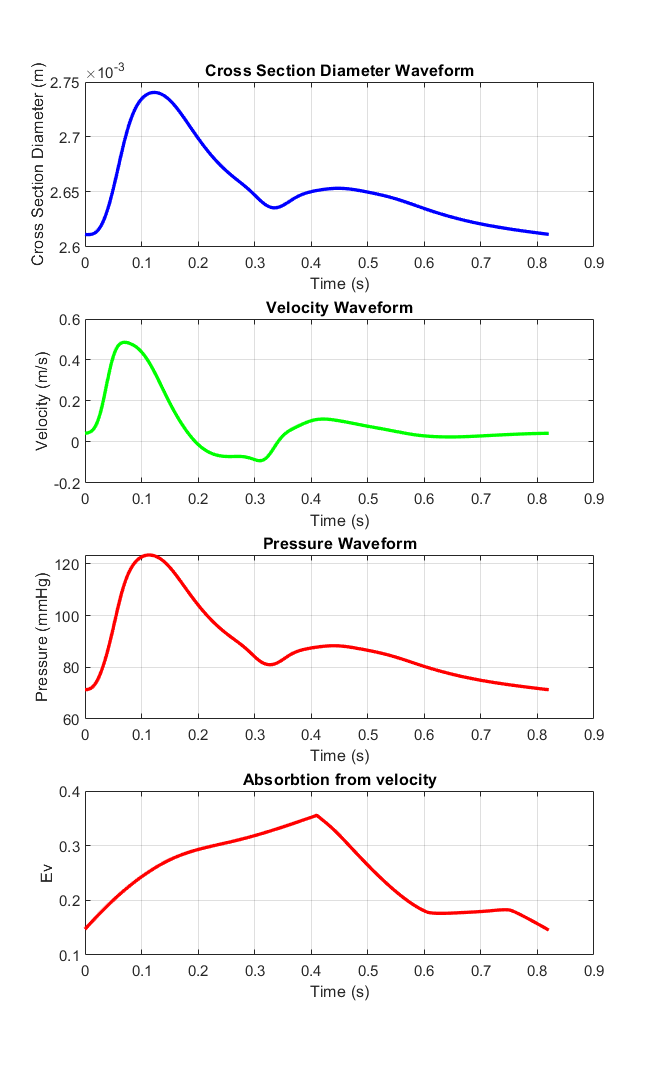

Error using waitbar (line 103)
The second argument must be a message character vector or a handle to an existing waitbar.

num_patients = 1;

A = pi*((2.56/2000)^2);
m_d =  1613;
k = (10^-6)/(A*60) ;
Qc =  328*k;

% Assuming you have the sampling frequency (fs) available
fs = data.waves.fs;

nd = 0.6875;
na = 0.3125;
tud = 0.39;
tua = 1.78;


for patient = 1:length(num_patients)
    
    cross_section = cell2mat(data.waves.A_Radial(patient));
    velocity = cell2mat(data.waves.U_Radial(patient));
    pressure = cell2mat(data.waves.P_Radial(patient));
    PPG = cell2mat(data.waves.PPG_Radial(patient));

    Diameter = sqrt((4/pi).*cross_section);

   
    num_samples = length(pressure);
    time = (0:num_samples-1) / fs;
    
    Q = velocity;
    y = sign(Q)*m_d.*(sqrt(abs(Q./Qc))./(1+sqrt(abs(Q./Qc))));
    norm_y =  y./max(y);
    
    delta = nd.*exp(-time./tud) + na.*exp(-time./tua);
    norm_delta = delta./sum(delta);
    ab = conv(norm_y,norm_delta,'same');
    
    % Plotting the waveforms
    figure;
    
    subplot(4,1,1);
    plot(time, Diameter, 'b', 'LineWidth', 2);
    title('Cross Section Diameter Waveform');
    xlabel('Time (s)');
    ylabel('Cross Section Diameter (m)');
    grid on;
    
    subplot(4,1,2);
    plot(time, velocity, 'g', 'LineWidth', 2);
    title('Velocity Waveform');
    xlabel('Time (s)');
    ylabel('Velocity (m/s)');
    grid on;
    
    subplot(4,1,3);
    plot(time, pressure, 'r', 'LineWidth', 2);
    title('Pressure Waveform');
    xlabel('Time (s)');
    ylabel('Pressure (mmHg)');
    grid on;

    subplot(4,1,4);
    plot(time, ab, 'r', 'LineWidth', 2);
    title('Absorbtion from velocity');
    xlabel('Time (s)');
    ylabel('Ev');
    grid on;
    
    pos = get(gcf, 'Position');
    set(gcf, 'Position',pos+[0 -500 0 500])
    
    parameters = num2cell(cat(2, Diameter, pressure, ab),2);
    
    nPhotonsCollected_values = zeros(size(time));
    
    % Create a progress bar
    h = waitbar(0, 'Processing...');
    
    % Loop over each pL1 value
    for i = 1:length(time)
        
        waitbar(i / length(time), h, sprintf('Processing... %d%%', round(i / length(time) * 100)));
        % Your existing code
        nPhotonsCollected_values(i) = model(parameters{i});
    end
    
    figure;
    plot(time, nPhotonsCollected_values, '-o');
    xlabel('t');
    ylabel('nPhotonsCollected');
    title('Simulation Results');
    
    close(h);
end